# Tnermoeconomic Analysis of a Combined Cycle

This Live Script makes a Thermoeconomic Analysis of a Combined Cycle, using the TaesLab functions.

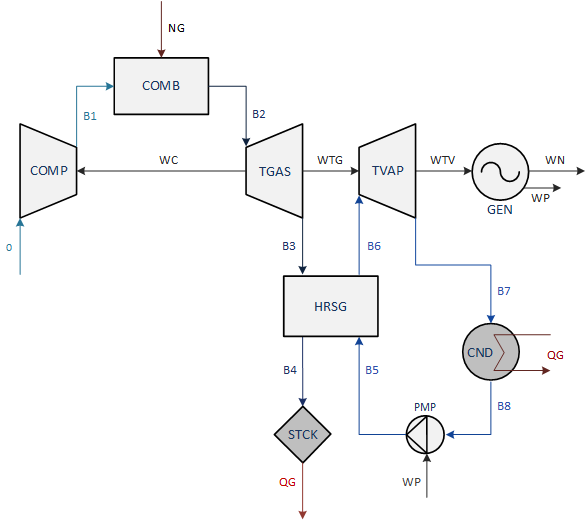

### Read Thermoeconomic Model

model = ThermoeconomicModel('ccplant_model.json','CostTables','ALL','Summary','STATES');

INFO: cDataModel. Productive Structure is valid
INFO: cDataModel. Format Definition is valid
INFO: cDataModel. Exergy values [REF] are valid
INFO: cDataModel. Exergy values [GT98] are valid
INFO: cDataModel. Exergy values [ST89] are valid
INFO: cDataModel. Exergy values [CMP84] are valid
INFO: cDataModel. Exergy values [ALT97] are valid
INFO: cDataModel. Exergy values [TG1080] are valid
INFO: cDataModel. Exergy values [PVAC8] are valid
INFO: cDataModel. Exergy values [NET85] are valid
INFO: cDataModel. Waste Definition is valid
INFO: cDataModel. Resources Cost sample [Base] is valid
INFO: cDataModel. Data model ccplant_model is valid
INFO: cThermoeconomicModel. Productive Diagram Active
INFO: cThermoeconomicModel. Set state REF
INFO: cThermoeconomicModel. Compute Diagram FP
INFO: cThermoeconomicModel. Compute thermoeconomic analysis for state REF
INFO: cThermoeconomicModel. Thermoeconomic diagnosis is not activated
INFO: cThermoeconomicModel. Recycle is not active
INFO: cThermoeconomic

model.setDebug(false);

### Show Summary Results

res=model.summaryResults;
stbls=res.ListOfTables;
ShowResults(res,'Table',char(stbls(7)));


Flows Direct Unit Exergy Cost (J/J) - SUMMARY

 key          REF      GT98      ST89     CMP84     ALT97    TG1080     PVAC8     NET85
————————————————————————————————————————————————————————————————————————————————————————
 A1        1.9398    1.9494    1.9398    1.9555    1.9397    1.9523    1.9415    1.9352
 A2        1.6871    1.6882    1.6872    1.6918    1.6871    1.6973    1.6886    1.6832
 A3        1.6871    1.6882    1.6872    1.6918    1.6871    1.6973    1.6886    1.6832
 A4        1.6871    1.6882    1.6872    1.6918    1.6871    1.6973    1.6886    1.6832
 V5        2.3185    2.3306    2.3275    2.3364    2.3377    2.3323    2.3281    2.3447
 V6        2.2279    2.2294    2.2293    2.2355    2.2281    2.2411    2.2544    2.2723
 V7        2.2279    2.2294    2.2293    2.2355    2.2281    2.2411    2.2544    2.2723
 V8        2.2279    2.2294    2.2293    2.2355    2.2281    2.2411    2.2544    2.2723
 NG        1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    

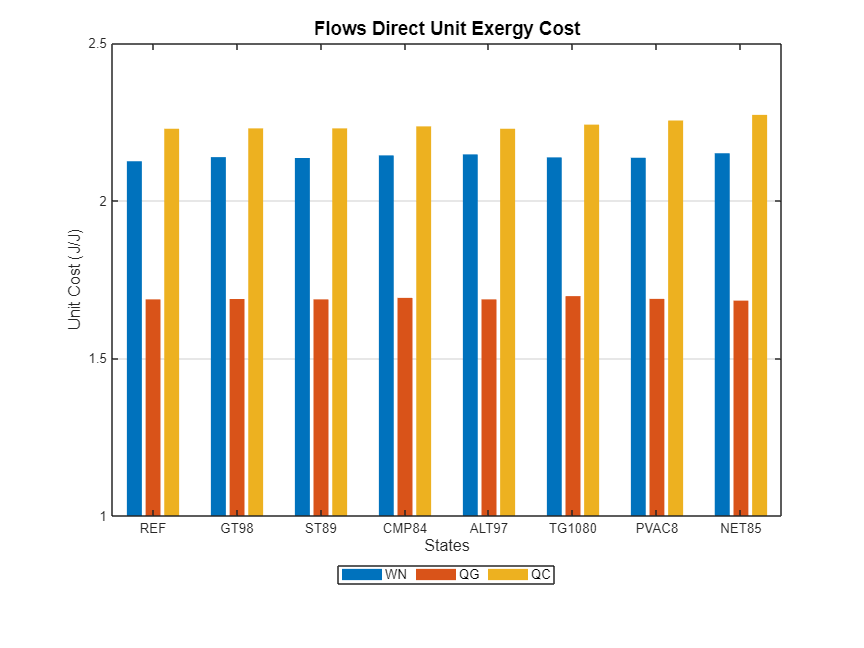

sgrphs=res.ListOfGraphs;
ShowGraph(res,'Graph',char(sgrphs(3)));

### Show Thermoeconomic Analysis for Reference State

ShowResults(model);


Flows Definition Table - REF

  Id Key  From     To       Type      
———————————————————————————————————————
   1 A1   COMP_P1  COMB_P1  INTERNAL  
   2 A2   COMB_P1  TGAS_F1  INTERNAL  
   3 A3   TGAS_F1  HRSG_F1  INTERNAL  
   4 A4   HRSG_F1  STCK_F1  INTERNAL  
   5 V5   PUMP_P1  HRSG_P1  INTERNAL  
   6 V6   HRSG_P1  TVAP_F1  INTERNAL  
   7 V7   TVAP_F1  COND_F1  INTERNAL  
   8 V8   COND_F1  PUMP_P1  INTERNAL  
   9 NG   ENV_R1   COMB_F1  RESOURCE  
  10 WC   TGAS_P1  COMP_F1  INTERNAL  
  11 WTG  TGAS_P1  ALTN_F1  INTERNAL  
  12 WTV  TVAP_P1  ALTN_F1  INTERNAL  
  13 WP   ALTN_P1  PUMP_F1  INTERNAL  
  14 WN   ALTN_P1  ENV_O1   OUTPUT    
  15 QG   STCK_P1  ENV_W1   WASTE     
  16 QC   COND_P1  ENV_W2   WASTE     


Productive Groups Definition Table - REF

  Id Key      Definition  Type      
—————————————————————————————————————
   1 COMB_F1  NG          FUEL      
   2 COMB_P1  A2-A1       PRODUCT   
   3 COMP_F1  WC          FUEL      
   4 COMP_P1  A1          PRODUCT   

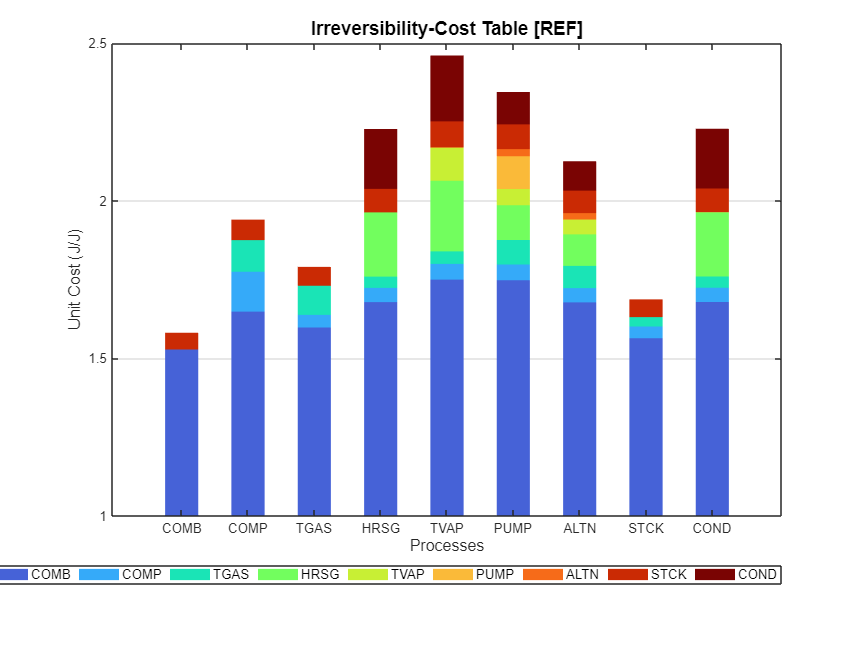

ShowGraph(model,'Graph',cType.Tables.PROCESS_ICT);

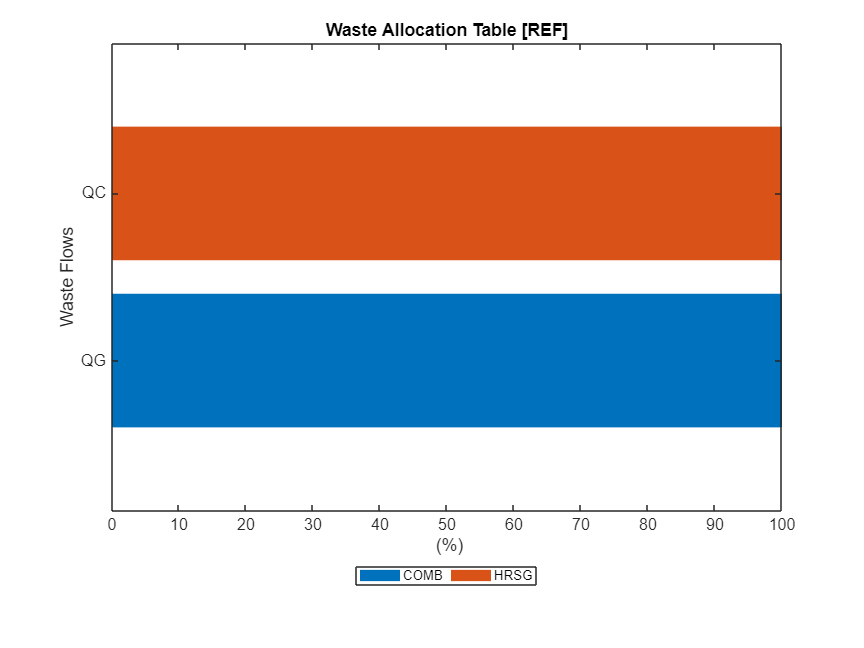

ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION,'PieChar',false);

#### Modify waste allocation

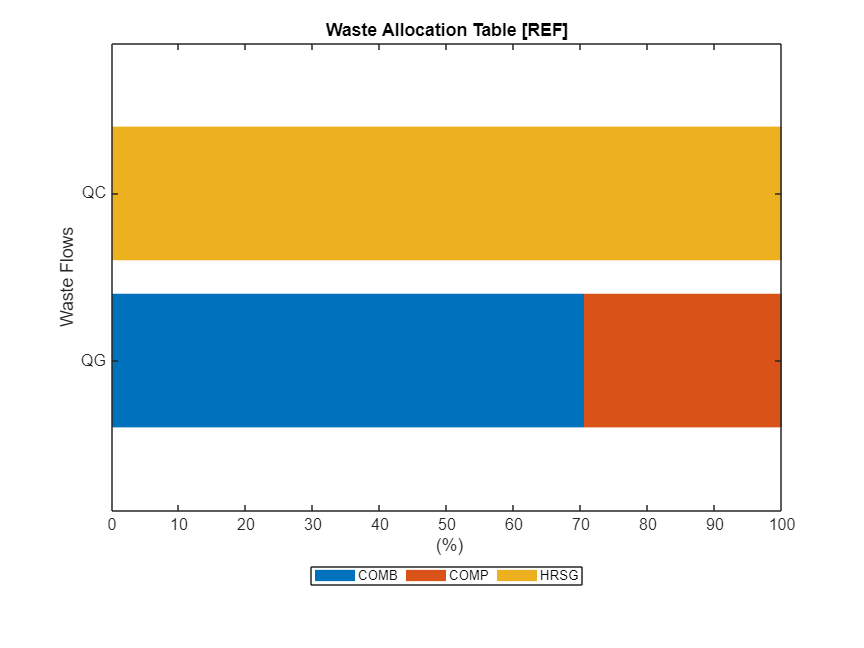

wastes=model.WasteFlows;
model.setActiveWaste(char(wastes(1)));
model.setWasteType('EXERGY');
ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION,'PieChart',false);

ShowResults(model,'Table',cType.Tables.PROCESS_COST);


Process Exergy Cost - REF

Key         P*(kW)    Pin*(kW)    Pex*(kW)      F*(kW)      R*(kW)
———————————————————————————————————————————————————————————————————
COMB      195911.6    191241.0      4670.6    191241.0      4670.6
COMP      103822.1     98448.9      5373.2    101862.2      1959.9
TGAS      194862.3    188332.6      6529.7    194862.3         0.0
HRSG      107745.2     94949.0     12796.2     98241.0      9504.2
TVAP       98900.7     87179.9     11720.8     98900.7         0.0
PUMP         659.8       608.8        51.0       659.8         0.0
ALTN      191900.8    177063.6     14837.2    191900.8         0.0
STCK        6630.5      6408.3       222.2      6630.5         0.0
COND        9504.2      8377.8      1126.4      9504.2         0.0



### Thermoeconomic Diagnosis

states=model.StateNames(2:end);
model.setState(char(states(7)))
res=model.thermoeconomicDiagnosis;
ShowResults(res,'Table',cType.Tables.DIAGNOSIS);


Diagnosis Summary - NET85

Key         MF(kW)      ΔI(kW)      ΔR(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)    ΔPt*(kW)
———————————————————————————————————————————————————————————————————————————————————————————
COMB         -0.86    -2920.00        0.00        0.00       -0.86        0.00        0.00
COMP          0.13     -194.00        0.00        0.00        0.23        0.00        0.00
TGAS          1.15     -292.00        0.00        0.00        1.75        0.00        0.00
HRSG       1014.12      403.30        0.00        0.00     1653.57        0.00        0.00
TVAP        467.94      132.00        0.00        0.00      923.05        0.00        0.00
PUMP         -0.00       -8.22        0.00        0.00       -0.00        0.00        0.00
ALTN          0.53     -103.30        0.00    -5000.00     -333.31        0.00   -10752.59
STCK          0.00        0.00     -430.00        0.00       -0.00     -365.45        0.00
COND          0.00        0.00      -34.78        0.00       

res.summaryDiagnosis;

Fuel Impact:        -8447.00 (kW)
Technical Saving:    2305.59 (kW)



printResults(res);


Diagnosis Summary - NET85

Key         MF(kW)      ΔI(kW)      ΔR(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)    ΔPt*(kW)
———————————————————————————————————————————————————————————————————————————————————————————
COMB         -0.86    -2920.00        0.00        0.00       -0.86        0.00        0.00
COMP          0.13     -194.00        0.00        0.00        0.23        0.00        0.00
TGAS          1.15     -292.00        0.00        0.00        1.75        0.00        0.00
HRSG       1014.12      403.30        0.00        0.00     1653.57        0.00        0.00
TVAP        467.94      132.00        0.00        0.00      923.05        0.00        0.00
PUMP         -0.00       -8.22        0.00        0.00       -0.00        0.00        0.00
ALTN          0.53     -103.30        0.00    -5000.00     -333.31        0.00   -10752.59
STCK          0.00        0.00     -430.00        0.00       -0.00     -365.45        0.00
COND          0.00        0.00      -34.78        0.00       

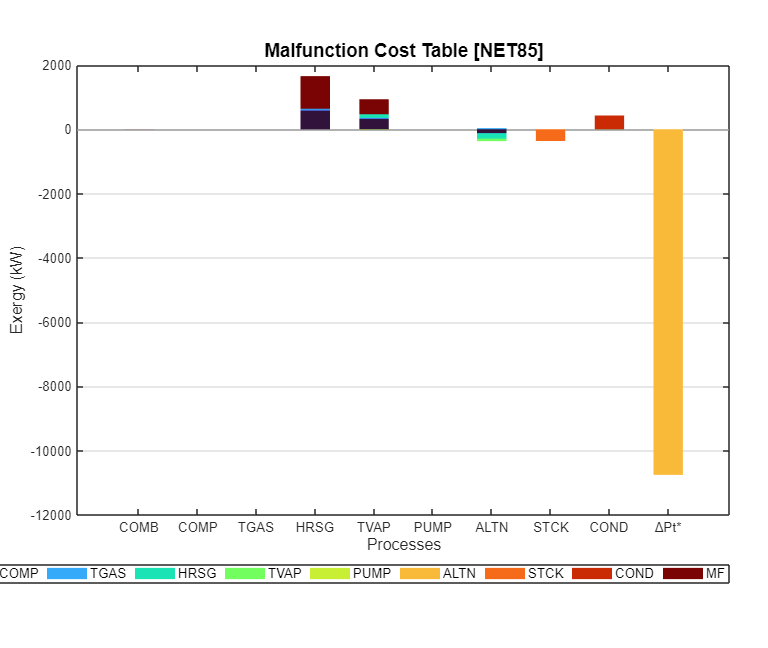

dgrphs=res.ListOfGraphs;
ShowGraph(res,'Graph',char(dgrphs(2)));